使用理论公式计算自由空间中贴片阵列对不同角度入射的反射系数

创建者：FTT

创建日期：2024.12.11

clear
clc
close all

贴片阵列参数

lambda = 1; %工作波长
D = lambda/10; %栅格周期
w = D/10; %条带宽度
epseff = 1; %等效均匀介质的有效介电常数
theta = linspace(0,pi/2,91); %入射角

常量

eps0 = 8.854*1e-12;
mu0 = 4*pi*1e-7;

中间量

k0 = 2*pi/lambda;
eta0 = sqrt(mu0/eps0); %自由空间波阻抗
keff = k0*sqrt(epseff); %入射波矢在等效均匀介质中的波数
etaeff = sqrt(mu0/eps0/epseff); %等效均匀介质中的波阻抗
alpha = keff*D/pi*log(1/sin(pi*w/2/D)); %栅格参数，论文中式（4）

栅格阻抗（贴片阵列）

ZgPatchTM = -1i*etaeff/2/alpha; %TM极化入射场的栅格阻抗，论文中式（8）
ZgPatchTE = -1i*etaeff/2/alpha./(1-k0^2/keff^2*sin(theta).^2/2); %TE极化入射场的栅格阻抗，论文中式（9）

自由空间阻抗

Z0TM = eta0.*cos(theta); %TM极化自由空间波阻抗
Z0TE = eta0./cos(theta); %TE极化自由空间波阻抗

使用传输线模型计算并联阻抗

ZinpTM = ZgPatchTM.*Z0TM./(ZgPatchTM+Z0TM); 
ZinpTE = ZgPatchTE.*Z0TE./(ZgPatchTE+Z0TE);

使用传输线模型计算贴片阵列反射系数

RTM = (Z0TM-ZinpTM)./(Z0TM+ZinpTM);
RTE = (Z0TE-ZinpTE)./(Z0TE+ZinpTE);

绘图

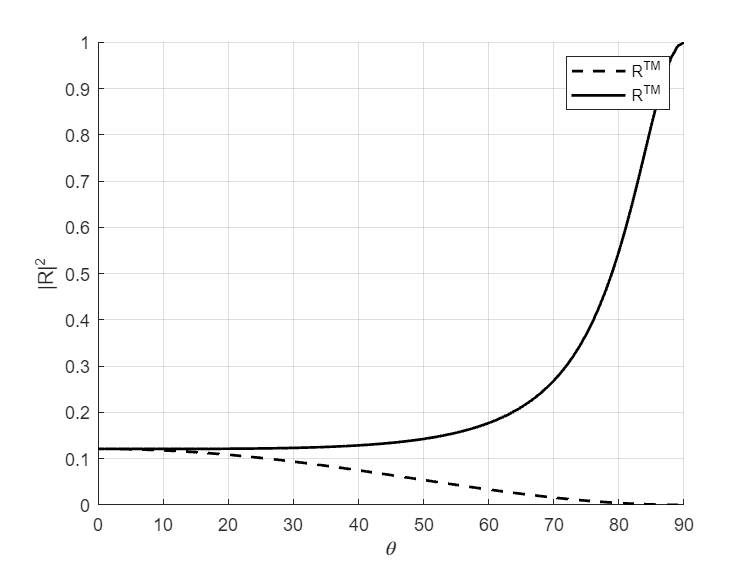

figure;
hold on
plot(theta*180/pi, abs(RTM).^2, 'k--', 'LineWidth', 1.5)
plot(theta*180/pi, abs(RTE).^2, 'k-', 'LineWidth', 1.5)
xlim([0 90])
ylim([0 1])
xlabel('\theta')
ylabel('|R|^2')
grid on
legend('R^{TM}','R^{TM}')